# Tutorial 3 - Modify Structural Parameters

## Introduction

In this tutorial, we will use a P2D model to simulate the effects of changing structural parameters (like electrode thickness or porosity) on cell discharge. After completing this tutorial, you should have a working knowledge of:

- Basics of how structural properties are defined in BattMo

- How changing the thickness of one electrode can affect the overall capacity of the cell

- How to setup and execute a parameter sweep

We'll use the same model from Tutorial 1.

jsonstruct = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

## Explore the Structural Parameters

Structural parameters are defined in the JSON parameter file and parsed into the MATLAB structure. Once the JSON parameter file has been read into MATLAB as a jsonstruct, its properties can be modified programmatically.

Let's begin by exploring the parameters of the negative electrode coating with the following command:

disp(jsonstruct.NegativeElectrode.Coating)

                thickness: 6.400000000000000e-05
    numberOfDiscreteCells: 10
         effectiveDensity: 1900
     bruggemanCoefficient: 1.500000000000000
           ActiveMaterial: [1×1 struct]
                   Binder: [1×1 struct]
       ConductingAdditive: [1×1 struct]


Here, we can see that the structural and material properties of the coating are defined. Let's try increasing the thickness of the negative electrode from 64 µm to 72 µm.

jsonstruct.NegativeElectrode.Coating.thickness = 72*micro;

Now we can run the simulation and plot the discharge curve against the discharged capacity of the cell.

% instantiate an empty figure
figure()
output = runBattery(jsonstruct);

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

retrieve the states from the simulation result

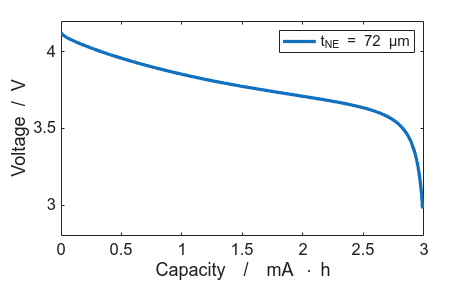

states = output.states;

% extract the time, voltage, and current quantities
time = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);
current = cellfun(@(state) state.('Control').I, states);

% calculate the capacity
capacity = time .* current;

% plot the discharge curve in the figure
plot((capacity/(hour*milli)), voltage, '-', 'linewidth', 3)
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend('t_{NE} = 72 µm')

## Setup and Run a Parameter Sweep

Now we can setup another parameter sweep to explore the effects of reducing the thickness of the negative electrode coating. Let's try simuating the cell performance with coating thickness values of 16 µm, 32 µm, and 64 µm. As in the previous tutorial, we will first create a vector contianing the desired thickness values. Then we will use a for-loop to iterate through the thickness values, modify the value in the jsonstruct, and run the simulation. We will then plot the results together for comparison.

% create a vector of diffent thickness values
thickness = [16, 32, 64].*micro;

% instantiate and empty cell array to store the outputs of the simulations
output = cell(size(thickness));

% instantiate an empty figure
figure()

% use a for-loop to iterate through the vector of c-rates
for i = 1 : numel(thickness)
    % modify the value for the c-rate in the control definition and update
    % the total duration of the simulation accordingly
    jsonstruct.NegativeElectrode.Coating.thickness = thickness(i);
    
    % run the simulation and store the results in the output cell array
    output{i} = runBattery(jsonstruct);
    
    % retrieve the states from the simulation result
    states = output{i}.states;
    
    % extract the time and voltage quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);
    current = cellfun(@(state) state.('Control').I, states);
    
    % calculate the capacity
    capacity = time .* current;
    
    % plot the discharge curve in the figure
    plot((capacity/(hour*milli)), voltage, '-', 'linewidth', 3)
    hold on
end

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

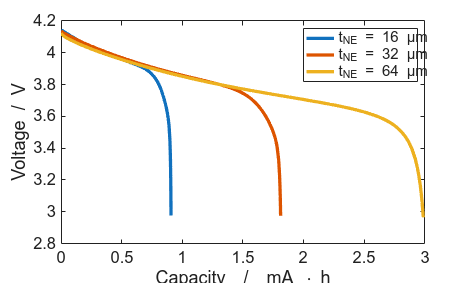

hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend('t_{NE} = 16 µm', 't_{NE} = 32 µm', 't_{NE} = 64 µm')

The results of this parameter sweep show that reducing the thickness of the negative electrode to 32 µm and 16 µm reduces its capacity such that it becomes the limiting factor in the overall capacity of the cell. Note that in real Li-ion batteries, the capacity of the negative electrode is usually oversized with respect to the capacity of the positive electrode to avoid dangerous lithium plating.

## Summary

In this tutorial, we explored how to modify structural parameters in BattMo. We first learned that structural properties of the electrodes are defined in the structure (e.g. NegativeElectrode.Coating). From there, it is possible to change individual parameter values and simulate the effects on the cell discharge. We then reviewed how to setup a parameter sweep and explored how changing the thickness of the negative electrode coating affects the overall capacity of the cell.

%{
Copyright 2021-2026 SINTEF Industry, Sustainable Energy Technology
and SINTEF Digital, Mathematics & Cybernetics.

This file is part of The Battery Modeling Toolbox BattMo

BattMo is free software: you can redistribute it and/or modify
it under the terms of the GNU General Public License as published by
the Free Software Foundation, either version 3 of the License, or
(at your option) any later version.

BattMo is distributed in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
GNU General Public License for more details.

You should have received a copy of the GNU General Public License
along with BattMo.  If not, see <http://www.gnu.org/licenses/>.
%}